# Post-processing

In object detection models like YOLO, **post-processing **is essential to refine the raw predictions made by the network. As we have seen in Lesson 2, these models tend to produce a large number of predictions.

This behavior is due to the model architecture, where:

- Each grid cell predicts multiple anchor boxes.

- Neighboring cells can detect the same object.

As a result, **several overlapping boxes may represent the same object**. If we keep all predicted boxes, the output would contain many duplicates.

To address this, post-processing includes:

- **Confidence thresholding**: Filters out low-confidence detections.

- **Non-Maximum Suppression (NMS)**: Removes redundant overlapping boxes, keeping only the most confident one.

This step ensures cleaner and more accurate results.

The objective of this lesson is to learn how to implement post-processing filters and understand how they can help us improve our results.

**Add Help Module Path**

First, we add the help module:

addpath('help-module');

## Loading a model 

Next, we load the model to which we will apply the post-processing techniques:

modelPath = fullfile(pwd, 'runs', 'detect', 'train10', 'weights');
configFile = fullfile(pwd, 'datasets', 'fruits_3_4998', 'data.yaml');

yolov8Det = utils.loadModel(modelPath, configFile);

## Exercise 1 - Confidence filter

Implement a confidence filter that removes detections with a confidence level below the threshold.

**Solution**

function filteredDetections  = filterByConfidence(detections, threshold)
    % Removes detections with confidence below a threshold.
    % Inputs:
    %   detections - Array of structs, each representing a detection result with fields:
    %                .boxes (Nx4): bounding boxes [x1 y1 x2 y2]
    %                .conf  (Nx1): confidence scores
    %                .cls   (Nx1): class labels
    %   threshold  - Scalar value specifying the minimum confidence score required to keep a detection
    %
    % Output:
    %   filteredDetections - Array of structs with low-confidence detections removed.
    
    n = numel(detections);
    filteredDetections = [];
    for i = 1:n
        detection = detections(i);
        conf = detection.conf;
        keep = conf >= threshold;
        if keep
           filteredDetections = [filteredDetections, detection];
        else
            fprintf('Filtered: removed low-confidence detection\n');
        end
    end
end 

In the following code, we define an anonymous function for the filter we implemented in the previous exercise, which we then use to create a post-processing component.

Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: r

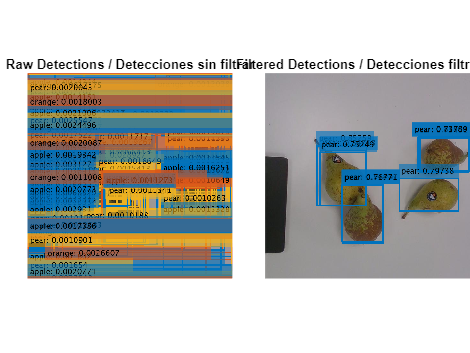

ScoreThreshold = 0.73;

removeLowScore = @(detections) filterByConfidence(detections, ScoreThreshold);
postprocessing = utils.PostProcessing(yolov8Det, {removeLowScore});

This post-processing component is used in the following code to apply our filter to the detections, which we can control using the *ScoreThreshold* variable.

utils.displayFilteredDetections(yolov8Det, 'pear.jpg', postprocessing);

## Exercise 2 - Confidence filter by classes

As in the previous exercise, you must implement a confidence filter that removes detections with a confidence score below a threshold. However, this time, each class should have its own custom threshold.


function filteredDetections = filterByClassConfidence(detections, thresholds)
    % Filters detections using a confidence threshold specific to each class.
    % Inputs:
    %   detections  - Array of structs, each representing detection results with fields:
    %                 .boxes (Nx4): bounding boxes
    %                 .conf  (Nx1): confidence scores
    %                 .cls   (Nx1): class labels (as integers starting from 1)
    %
    %   thresholds  - Vector of class-specific confidence thresholds.
    %                 thresholds(i) is the minimum confidence required for class i.
    %
    % Output:
    %   filteredDetections - Array of structs with low-confidence detections removed,
    %                        where filtering is applied per class using corresponding thresholds.

    n = numel(detections);
    filteredDetections = [];  % preallocate struct array
    for i = 1:n
        detection = detections(i);

        cls = detection.cls;
        conf = detection.conf;
        keep = conf >= thresholds(cls);
           
        if keep
            filteredDetections = [filteredDetections, detection];
        else
            fprintf('Filtered: removed low-confidence detections (per class)\n');
        end
    end
end 

% Threshold vector per class (index = class)
appleThreshold = 0.66;
orangeThreshold = 0.45;
pearThreshold = 0.61;

scoreThresholds = [appleThreshold, orangeThreshold, pearThreshold];
removeLowScorePerClass = @(detections) filterByClassConfidence(detections, scoreThresholds)

removeLowScorePerClass = function_handle with value:
    @(detections)filterByClassConfidence(detections,scoreThresholds)


Filtered: removed low-confidence detections (per class)
Filtered: removed low-confidence detections (per class)
Filtered: removed low-confidence detections (per class)
Filtered: removed low-confidence detections (per class)
Filtered: removed low-confidence detections (per class)
Filtered: removed low-confidence detections (per class)
Filtered: removed low-confidence detections (per class)
Filtered: removed low-confidence detections (per class)
Filtered: removed low-confidence detections (per class)
Filtered: removed low-confidence detections (per class)
Filtered: removed low-confidence detections (per class)
Filtered: removed low-confidence detections (per class)
Filtered: removed low-confidence detections (per class)
Filtered: removed low-confidence detections (per class)
Filtered: removed low-confidence detections (per class)
Filtered: removed low-confidence detections (per class)
Filtered: removed low-confidence detections (per class)
Filtered: removed low-confidence detections (per

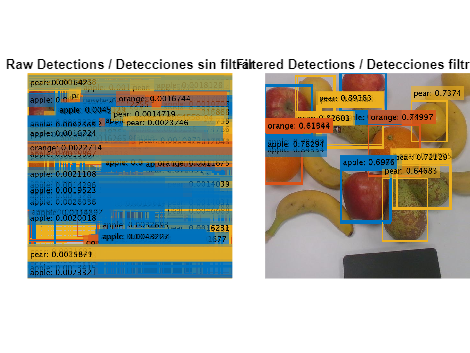

postprocessing = utils.PostProcessing(yolov8Det, {removeLowScorePerClass});

utils.displayFilteredDetections(yolov8Det, 'multiple.jpg', postprocessing);

## Intersection over Union (IoU) 

In object detection, a fundamental concept is **Intersection over Union (IoU)**. This metric quantifies the overlap between two bounding boxes: the **predicted box** from the model and the **ground truth box**. IoU is used to assess how accurate a prediction is in relation to the actual annotation.

Formally, IoU is defined as the ratio between the area of intersection and the area of union of the two boxes:

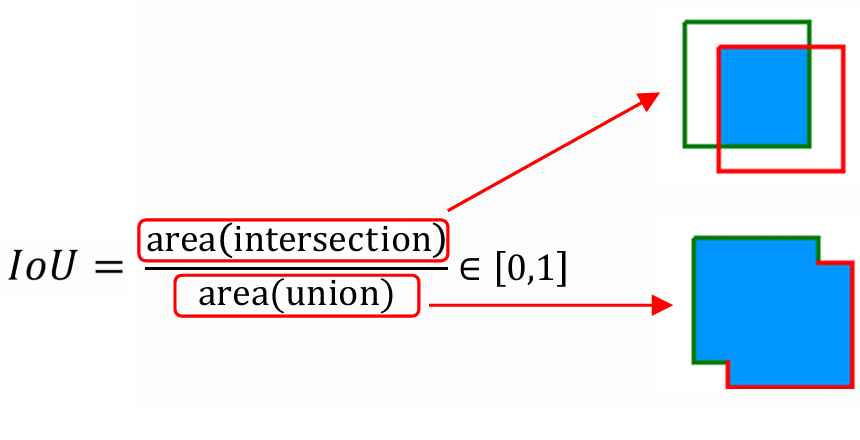

The value of IoU is bounded between 0 and 1:

- **IoU = 0** means there is no overlap.

- **IoU = 1** indicates a perfect match between the prediction and the ground truth.

## Exercise 3 - Calculate IoU

Implement a function that calculates the Intersection over Union of two bounding boxes:

**Hint**


$$\textrm{union}={\textrm{area}}_1 +{\textrm{area}}_2 -\textrm{intersection}$$


function iou = calculateIoU(b1, b2)
    % Calculates the Intersection over Union (IoU) between two bounding boxes.
    %
    % Inputs:
    %   b1 - 1x4 vector representing the first bounding box [x1 y1 x2 y2]
    %   b2 - 1x4 vector representing the second bounding box [x1 y1 x2 y2]
    %
    % Output:
    %   iou - Scalar value between 0 and 1 representing the IoU.
    %         IoU = 0 if there is no overlap.
    %         IoU = 1 if boxes are identical.

    x1 = max(b1(1), b2(1));
    y1 = max(b1(2), b2(2));
    x2 = min(b1(3), b2(3));
    y2 = min(b1(4), b2(4));
    inter = max(0, x2-x1) * max(0, y2-y1);
    area1 = (b1(3)-b1(1))*(b1(4)-b1(2));
    area2 = (b2(3)-b2(1))*(b2(4)-b2(2));
    union = area1 + area2 - inter;
    if union>0
        iou = inter/union;
    else
        iou = 0;
    end
   
end

#### **Test**

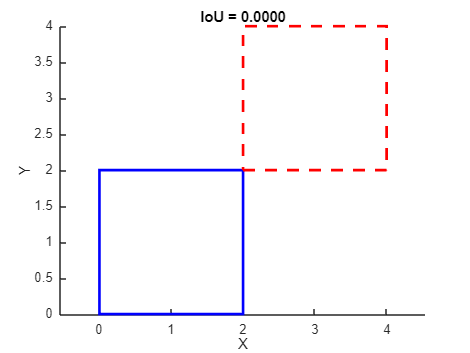

utils.displayIoU([0 0 2 2], [2 2 4 4], @calculateIoU) % expected 0

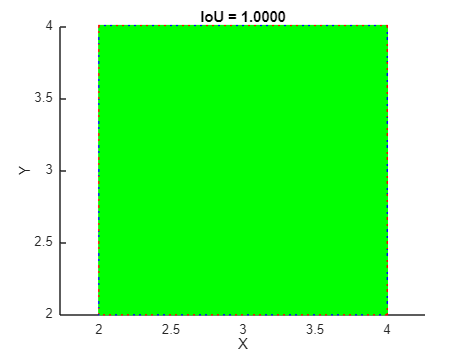

utils.displayIoU([2 2 4 4], [2 2 4 4], @calculateIoU) % expected 1

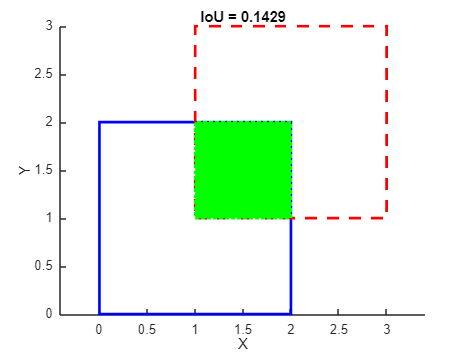

utils.displayIoU([0 0 2 2], [1 1 3 3], @calculateIoU) % expected 0.1429

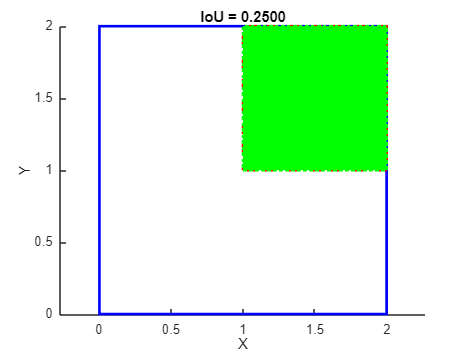

utils.displayIoU([0 0 2 2], [1 1 2 2], @calculateIoU) % expected 0.25

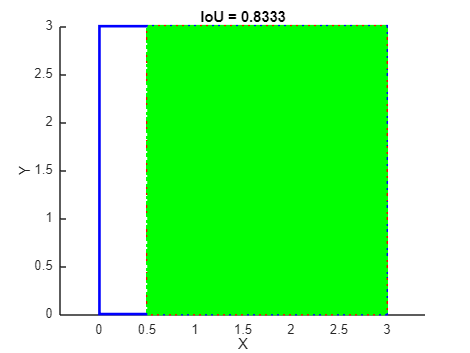

utils.displayIoU([0 0 3 3], [0.5 0 3 3], @calculateIoU); % Expectected 0.8333

## Exercise 4 - Non-Maximum Suppression

In this exercise, your goal is to implement **Non-Maximum Suppression (NMS)** to eliminate redundant overlapping detections of the same class.

**How NMS Works**

The basic NMS algorithm consists of these steps:

- **Filter by Confidence Score: **Remove all boxes with confidence (objectness × class probability) below a threshold (e.g., `0.25`).

- **Sort Boxes by Score: **Arrange the remaining boxes in descending order of their confidence scores.

- **Suppress Overlapping Boxes:**

- Take the box with the highest confidence, call it `B1`.

- Compute the **IoU (Intersection over Union)** of `B1` with all other boxes:IoU

- `IoUThreshold` (e.g., `0.5`), discard those boxes since they likely represent the same object.

- Repeat with the next remaining box.

**Hint**

Use the following function to convert bounding boxes into the format required by the `calculateIoU` function:

function boxXYXY = xywh2xyxy(boxXYWH)
    % Convert [x y w h] into [x1 y1 x2 y2]
    boxXYXY = [boxXYWH(1), ...
               boxXYWH(2), ...
               boxXYWH(1) + boxXYWH(3), ...
               boxXYWH(2) + boxXYWH(4)];
end

function filteredDetections = filterByOverlapping(detections, iouThreshold, calculateIoU)
    % Removes overlapping detections based on Intersection over Union (IoU).
    % Inputs:
    %   detections    - Array of Struct containing detection results with fields:
    %                  .boxes (Nx4): bounding boxes [x1 y1 x2 y2]
    %                  .conf  (Nx1): confidence scores
    %                  .cls   (Nx1): class labels
    %   iouThreshold - Scalar threshold for IoU. Detections with IoU above this 
    %                  value (and same class) are considered duplicates.
    %   calculateIoU  - Function handle to compute IoU between two boxes.
    %
    % Output:
    %   filteredDetection - Detection struct with overlapping boxes removed,
    %                       keeping the one with higher confidence.
    

    % Extract individual detection components
    boxes = vertcat(detections.boxes);  % Nx4
    conf  = vertcat(detections.conf);   % Nx1
    cls   = vertcat(detections.cls);    % Nx1
    
    N = size(boxes, 1);         % Total number of detections

    % Sort detections by descending confidence
    [~, order] = sort(conf, 'descend');

    keep = false(N,1);          % Boolean mask to track which boxes to keep
    
    % Iterate over detections in sorted order
    for k = 1:N
        idx = order(k);         % Index of the current detection
        keepThis = true;        % Flag indicating whether to keep the current box

        % Compare with previously kept boxes
        for j = find(keep)'     % Indices of already kept boxes
            if cls(idx) == cls(j)   % Only compare boxes of the same class
                iou = calculateIoU(xywh2xyxy(boxes(idx,:)), xywh2xyxy(boxes(j,:)));
                if iou > iouThreshold
                    keepThis = false;
                    break;
                end
            end
        end

        if keepThis
            keep(idx) = true;
        end
    end

    % Keep only selected detections
    filteredDetections.boxes = boxes(keep,:);
    filteredDetections.conf  = conf(keep);
    filteredDetections.cls   = cls(keep);

    removed = sum(~keep);
    if removed > 0
        fprintf('Filtered: removed %d overlapping detections\n', removed);
    end
end



ScoreThreshold = 0.5;
removeLowScore = @(detections) filterByConfidence(detections, ScoreThreshold);

Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: r

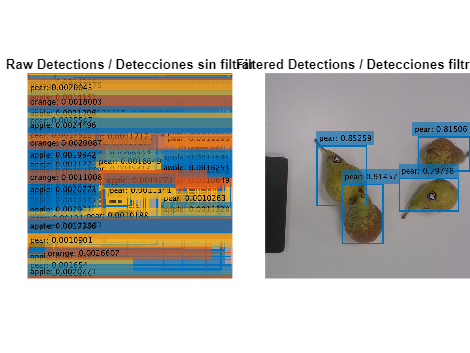

iouThreshold = 0.5;
removeOverlapping = @(detections) filterByOverlapping(detections, iouThreshold, @calculateIoU);

Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: r

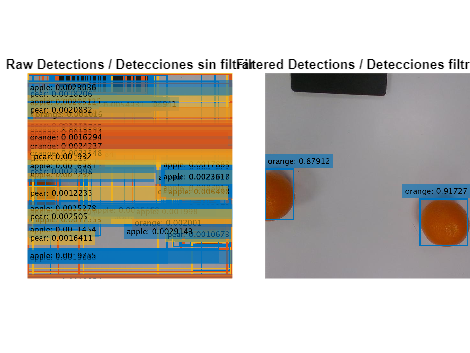


filters = {removeLowScore, removeOverlapping};

Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: r

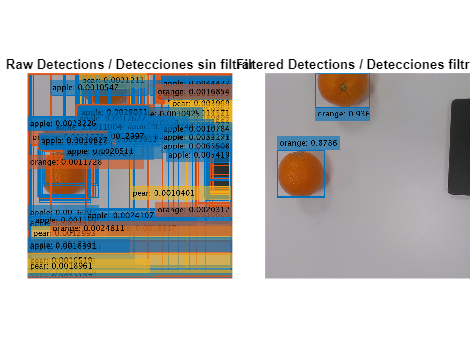

postprocessing = utils.PostProcessing(yolov8Det, filters);

Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: r

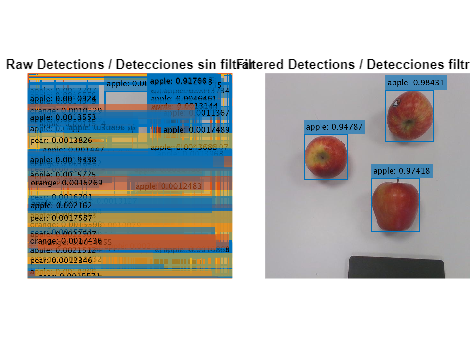

utils.displayFilteredDetections(yolov8Det, 'pear.jpg', postprocessing);


Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: r

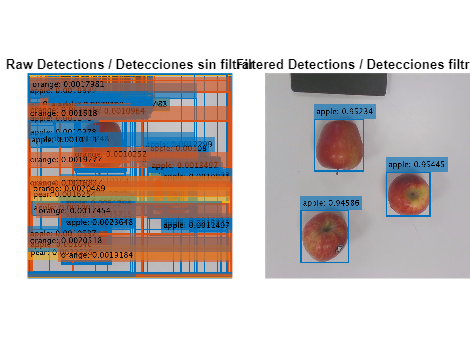

utils.displayFilteredDetections(yolov8Det, 'orange.jpg', postprocessing);
utils.displayFilteredDetections(yolov8Det, 'orange2.jpg', postprocessing);

Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: removed low-confidence detection
Filtered: r

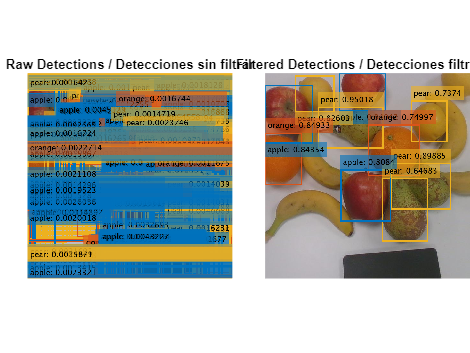


utils.displayFilteredDetections(yolov8Det, 'apple.jpg', postprocessing);


utils.displayFilteredDetections(yolov8Det, 'apple2.jpg', postprocessing);


utils.displayFilteredDetections(yolov8Det, 'multiple.jpg', postprocessing);

Now, after filtering the predictions, we obtain good results; however, we have no idea how good the model actually is.

In the next lesson, we will address this question.